images\seashell_five.jpg


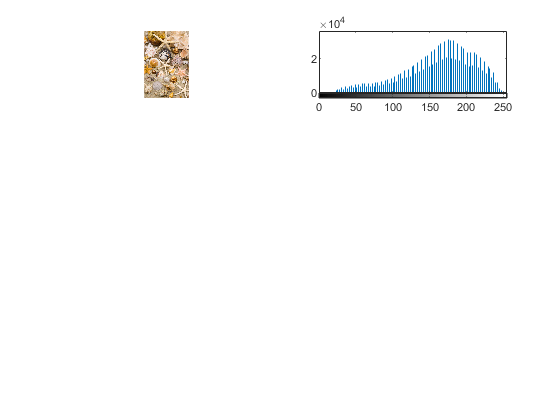

images\shellfish_four.jpg


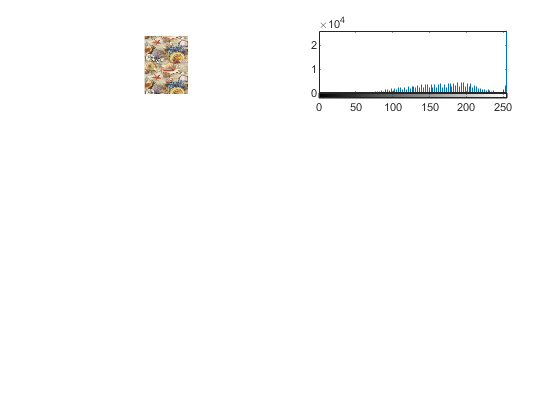

images\starfish.jpg


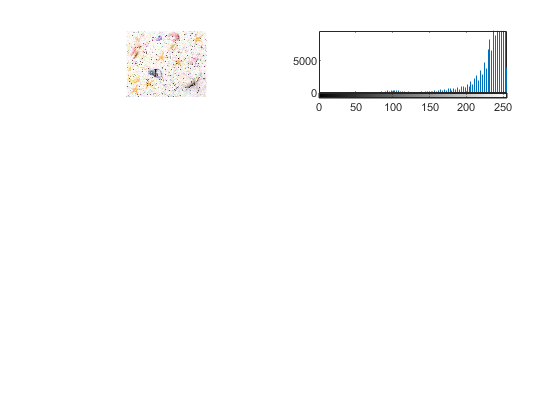

images\starfish_17.jpg


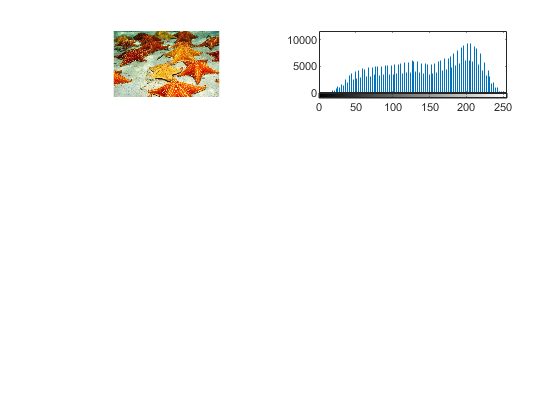

images\starfish_5.jpg


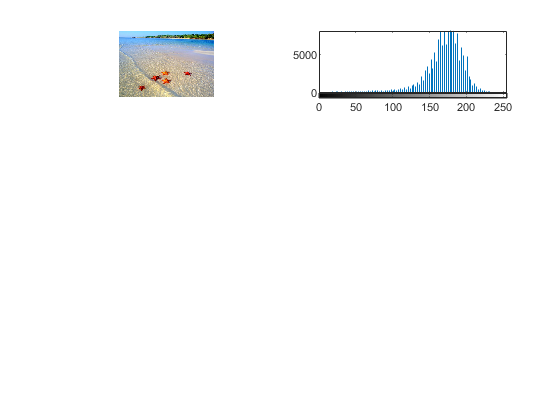

images\starfish_map0.jpg


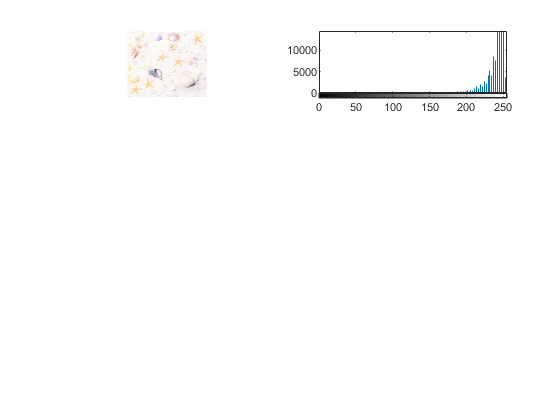

images\starfish_map1.jpg


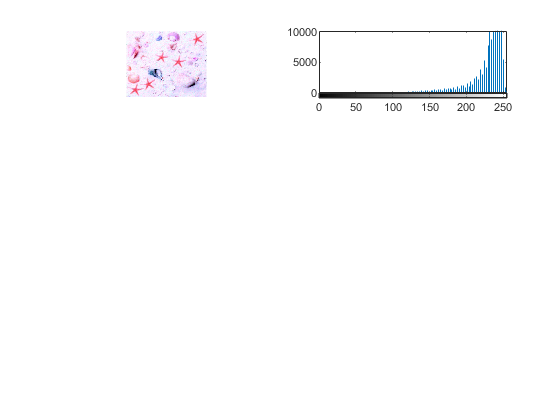

images\starfish_map2.jpg


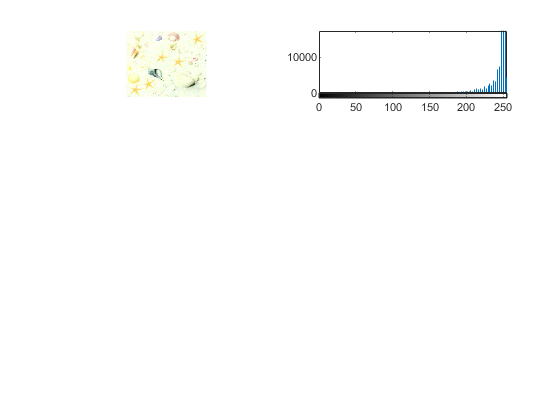

images\starfish_map3.jpg


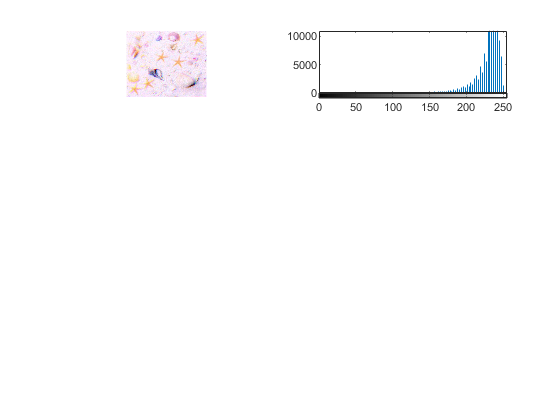

images\starfish_noise1.jpg


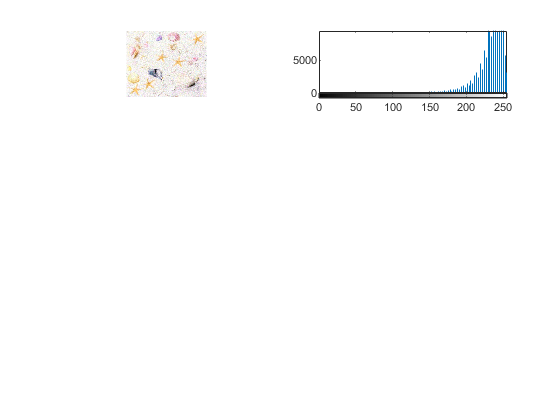

images\starfish_noise10.jpg


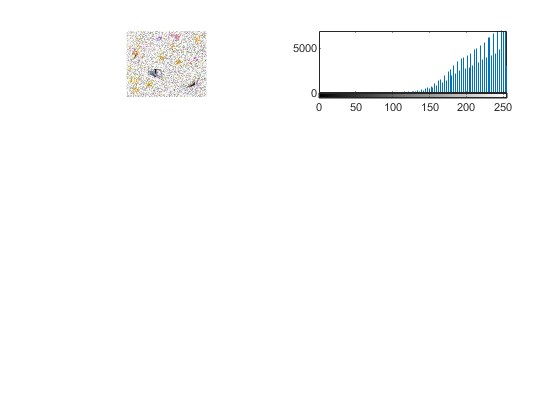

images\starfish_noise2.jpg


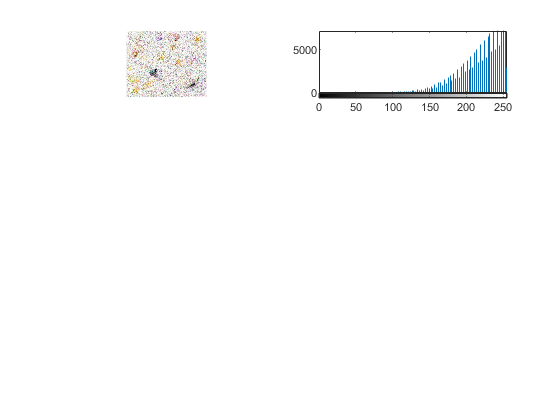

images\starfish_noise3.jpg


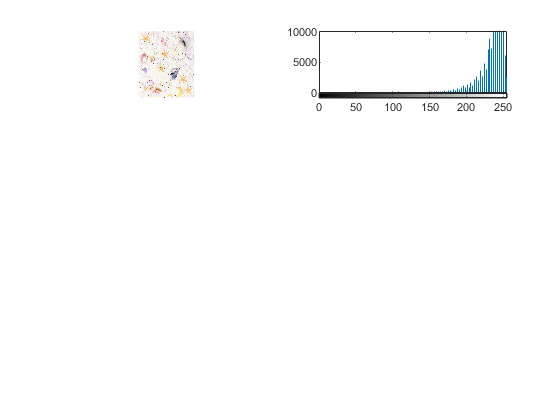

images\starfish_noise4.jpg


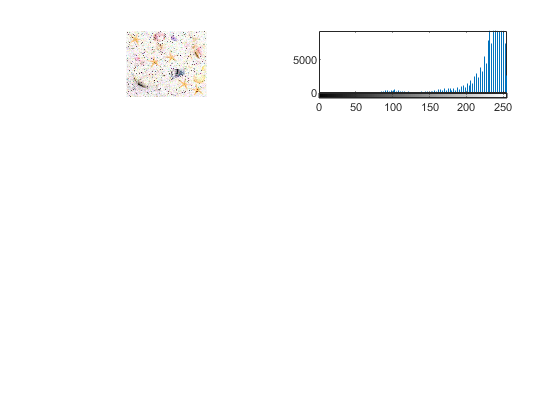

images\starfish_noise5.jpg


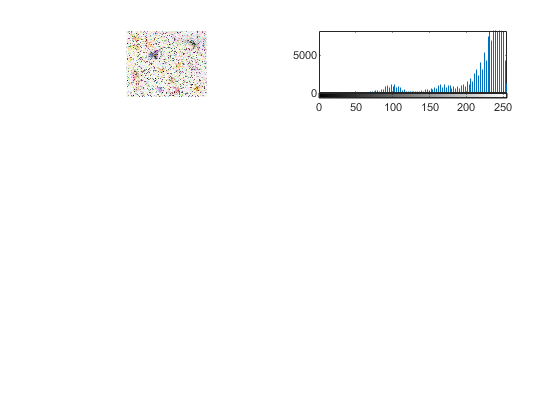

images\starfish_noise6.jpg


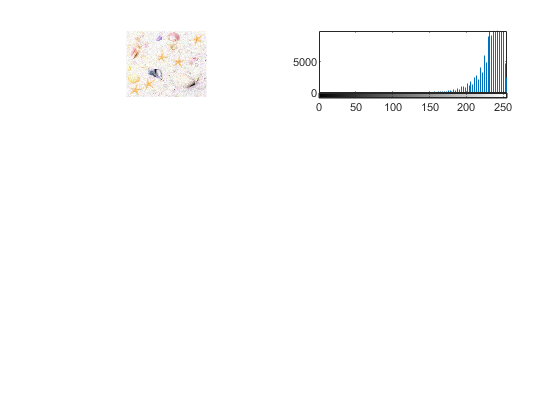

images\starfish_noise7.jpg


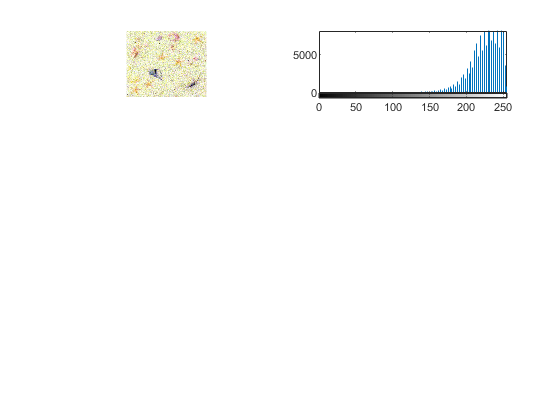

images\starfish_noise8.jpg


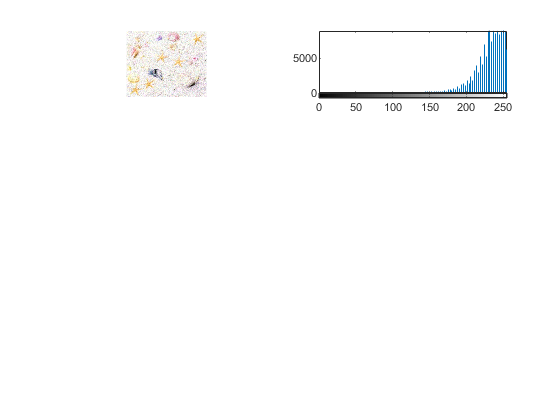

images\starfish_noise9.jpg


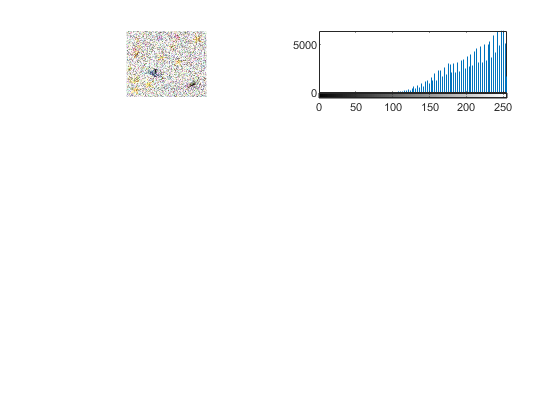

images\starfish_overlaid.jpg


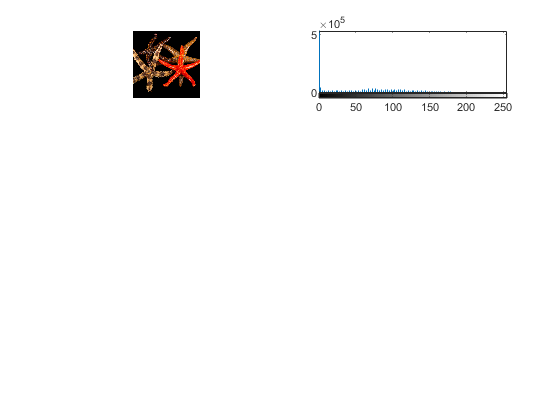

files = GetFilesInSubDir("images");

r = 4;
c = 2;
for i = 1:numel(files)
    filepath = files(i);
    
    disp(filepath)
    
    im = imread(filepath);
    
%     im = rgb2hsv(im);
    [ch1, ch2, ch3] = imsplit(im);
    
    figure
    subplot(r,c,1);
    imshow(im)
    subplot(r,c,2);
    allChHist = imhist(rgb2gray(im));
    imhist(rgb2gray(im), 100)
    
end

function filepaths = GetFilesInSubDir(subDir)
    files = dir(subDir);
    files = files(~ismember({files.name}, {'.', '..'})); % Remove navigation elements from struct.
    filepaths = subDir + "\" + {files.name};
end